# Man On The Moon

[⇦ Overview](matlab:open('./Overview.html'))

Conservation of Mass and Momentum are the fundamental equation of fluid dynamics. This script investigates their application to the modeling of the launch of one of the most famous space exploration missions, comparing the results to the actual flight log from the mission.

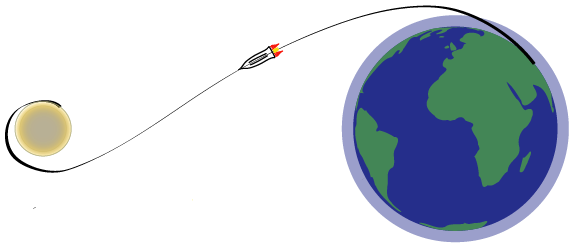

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon  at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://www.mathworks.com/learn/tutorials/matlab-onramp.html), a free 2 hour online tutorial that teaches the essentials of MATLAB.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## Introduction

From 1961 to 1972, NASA pursued the Apollo space exploration program. Named after the Greek god of the sun, the program’s principal objective was to establish the first human presence on the Moon. On July 16th, 1969, the Apollo 11 mission launched from Cape Canaveral, Florida. The mission Commander, Neil Armstrong, would become the first astronaut to set foot on the Moon. In this script, we will use the mass and momentum conservation equations to study the first phase of this mission’s launch.

The rocket used to send the small, crewed spacecraft into Earth orbit, and later on the way to the Moon, was the Saturn V. The first phase of the launch consisted of the complete burnout of the rocket’s first phase. Until November 2022, this rocket was the most powerful to launch a space exploration mission. 

  **Try**. To understand the sheer size of the Saturn V rocket, click the following button to compare its size to a football field at the same scale.

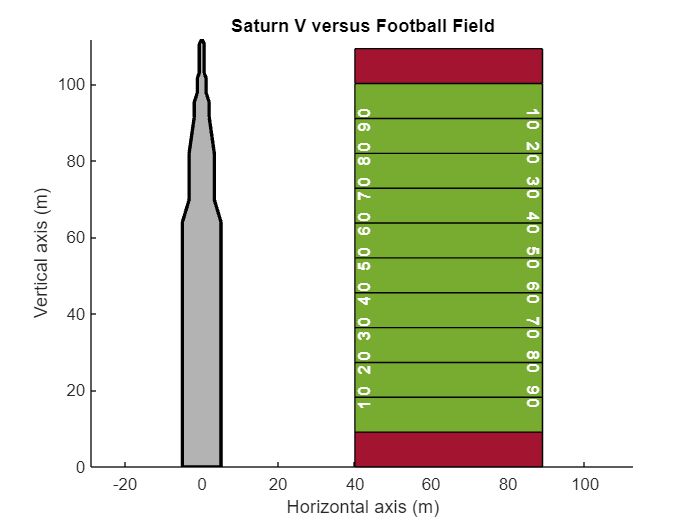

 
figure()
DrawSaturn(DrawFootball=true);
title("Saturn V versus Football Field")

## Control Volume and Control Surfaces 

 **Definition. **In fluid dynamics, the control volume method applies the integral form of a conservation equation to a constant abstract volume in space.

  **Pro-tip**. The first step of this method always consists of the careful definition of this abstract control volume in space.

  **Try**.Use the following drop-down to explore three different definitions of the control volume that could be used to study the rocket launch.

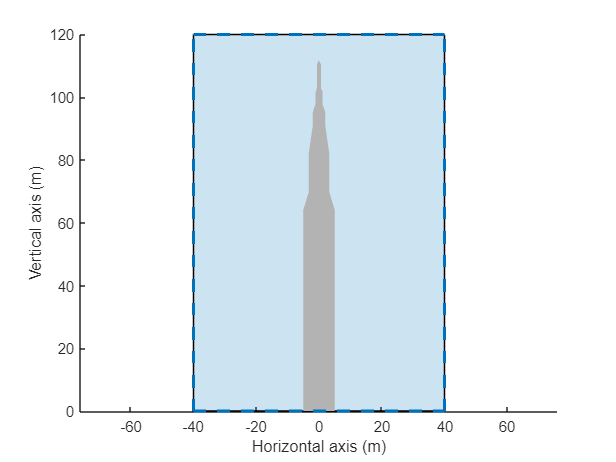

figure()
DrawSaturn(ControlVolume = 3);

 **Exercise.** Which of the following control volumes seems to be the most adequate for this problem?

qControlVolumeDefinition("Second");

Good job!


Now that an appropriate control volume is defined, we can also look at breaking down the surface enclosing the volume into multiple control surfaces.

  **Try**. Explore the definition of the control volume and control surfaces used throughout this script.

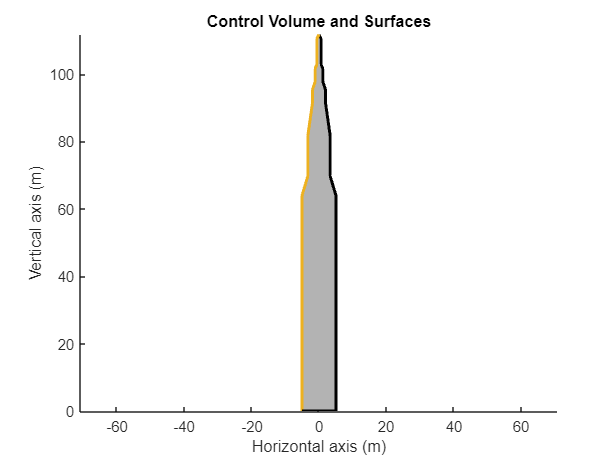

IntroControlVolume("CSL");

Solving the integral form of the conservation equation necessarily involves the integration of fluxes through the control surfaces. This step is a common source of error, as it is easy to commit sign mistakes in the dot product of the flux along the control surface. 


$$\int_{CS} {\bf Flux}\cdot {\bf NormalVector} \text{ } dS$$
                 
$$(\star)$$


By convention, we define the normal vectors to the control surfaces so that a flux leaving the control volume will be a positive contribution to integral $(\star)$, and if a flux is entering the control volume it will be a negative contribution. 

 **Exercise.** What is the direction of the normal vector to the bottom control surface to satisfy this convention?

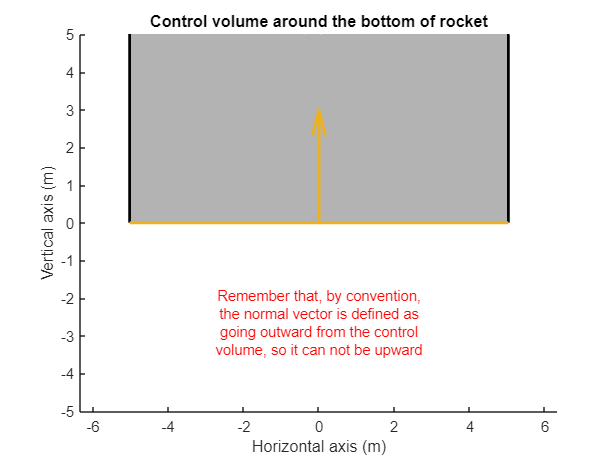

qNormalBottomSurface("Upward");

  **Pro-tip**. Formally defining the normal to the control surfaces early in the problem helps avoid sign errors later in the derivation. 

  **Try**. Use the following drop-down control to visualize the normal vector over each control surface.

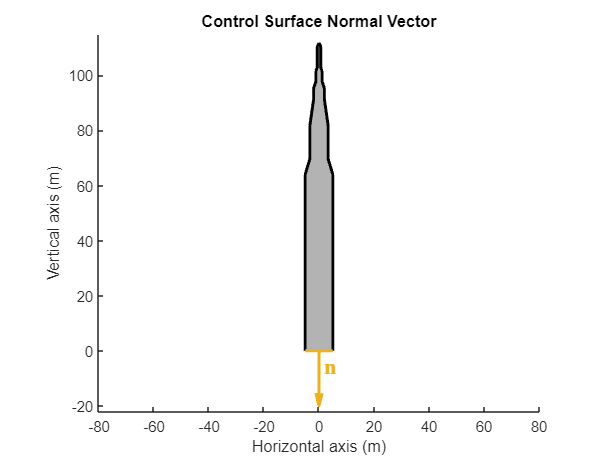

LookAtNormalVector("CSB");

## Solve the Mass Conservation Equation

Now that the control volume and the control surfaces are formally defined, we can start studying the Saturn V rocket. The goal of this script will be to describe the acceleration, velocity, and altitude of the Saturn V rocket throughout the first stage of the launch. It is usually recommended to apply the mass conservation equation first.

** Definition. **Integral Form of the Mass Conservation Equation


$$\frac{\partial}{\partial t}\int_{CV}\rho dV+\int_{CS} ({\bf u}\cdot{\bf n})\rho dS$$


The input parameters of the problem are the initial mass of the rocket $m_0
$, the rocket engine exhaust velocity $u_e$, the rocket exhaust mass flow $\dot{m_e}$ and the total mass of propellant burned during the first phase of the launch $m_p$.

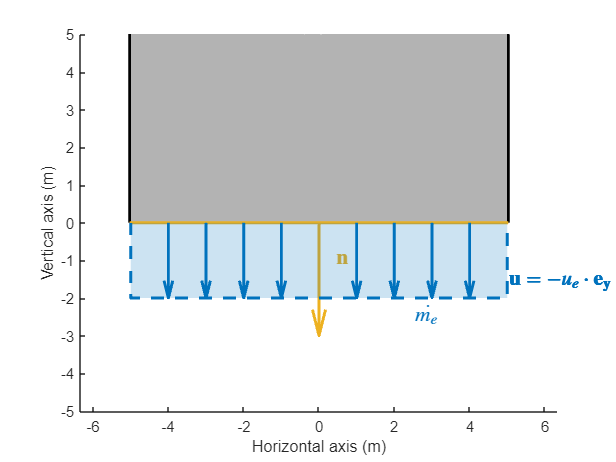

figure()
DrawSaturn(Highlight="CSB", ZoomIn=true, NormalVector=true, DrawExhaustVelocity=true, ...
    WriteExhaustVelocity=true, DrawExhaustMassFlow=true, WriteExhaustMassFlow=true);

### **Simplifying Mass Conservation**

   **Pro-tip.** The first step in solving any problem using the integral form of a conservation equation is to break down the integral into components for each control volume and control surface.


$$\frac{\partial}{\partial t}\int_{CV}\rho dV+\int_{CS} ({\bf u}\cdot{\bf n})\rho dS = \\

\underbrace{\frac{\partial}{\partial t}\int_{CV}\rho dV}_\text{A}
+
\underbrace{\int_{CS_{right}} ({\bf u}\cdot{\bf n})\rho dS }_\text{B}
+
\underbrace{\int_{CS_{left}} ({\bf u}\cdot{\bf n})\rho dS }_\text{C}
+
\underbrace{\int_{CS_{bottom}} ({\bf u}\cdot{\bf n})\rho dS }_\text{D}
= 0$$
               
$$(\heartsuit)$$


  **Pro-tip. **The second step should be to simplify this expression by identifying terms equal to zero. Note that some problems might have no term equal to zero.

 **Exercise.** In our case, identify the term equal to zero if any.

qNullTermMass(A = false, B = true, C = true, D = false);  

Good job! You indentified all of the null term in the mass conservation equation.


### Derivation of Inertial Term

Now that the mass conservation equation $(\heartsuit)$ has been simplified as much as possible, it is time to derive the remaining term, starting with the inertial term.

 **Exercise.** How can the inertial term A be expressed?


$$\text{A) } \frac{\partial m(t)}{\partial t} 
\quad\quad
\text{B) } {\bf u}\cdot \frac{\partial m(t)}{\partial t}
\quad \quad
\text{C) } u_e \frac{\partial m(t)}{\partial t}
\quad \quad
\text{D) } \frac{\partial m(t)\times t}{\partial t}$$


qInertiaMass(0);

### Derivation of Mass Flux Term

The remaining integral term in the mass conservation equation $(\heartsuit)$ consists of the mass flux through the bottom control surface.


$$\int_{CS_{bottom}} ({\bf u}\cdot{\bf n})\rho dS 
$$


 **Exercise. **Simplify $\bf u\cdot \bf n$.


$$\text{A) }{\bf u}\cdot{\bf n} = -u_e
\quad\quad
\text{B) }{\bf u}\cdot{\bf n} = u_e$$


qDotProductMass(2);

Good job! The vectors are in the same direction so the scalar product is postive.


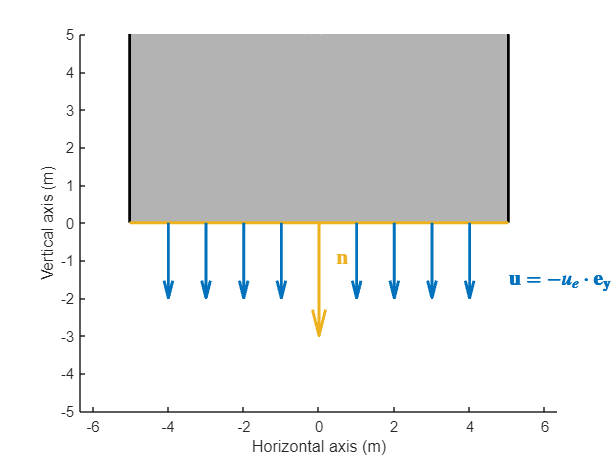

figure()
DrawSaturn(Highlight="CSB", ZoomIn=true, NormalVector=true, DrawExhaustVelocity=true, WriteExhaustVelocity=true);

Now that the dot product is out of the way, it is time to integrate over the control surface.


$$\int_{CS_{bottom}} ({\bf u}\cdot{\bf n})\rho dS 

=
\int_{CS_{bottom}} \rho u_e dS
$$


 **Exercise.** Express the integral results in terms of the input parameters of the problem.


$$\text{A) } {\bf u}\cdot\dot{m_e}
\quad\quad
\text{B) } -u_e\dot{m_e} 
\quad\quad
\text{C) } \dot{m_e}
$$


qMassFlowTerm(3); 

Good job! The remaining term in the mass conservation equation represent the mass flow leaving the control volume through the bottom Control Surface.


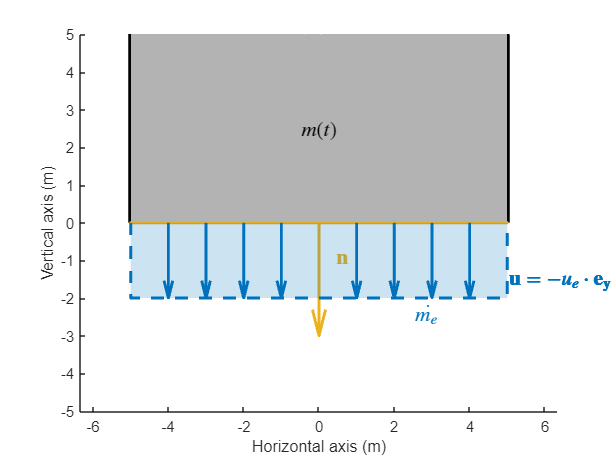

figure()
DrawSaturn(ZoomIn=true, Highlight="CSB", NormalVector=true, DrawExhaustVelocity=true, WriteExhaustVelocity=true, ...
    DrawExhaustMassFlow=true, WriteExhaustMassFlow=true, WriteMass=true);

### Solution Mass Conservation Equation

The final form of the mass conservation equation $(\heartsuit)$ for this rocket model consists of the differential equation:


$$\frac{\partial m(t)}{\partial t}  + \dot{m_e} = 0$$


** Assumption. **Let's say the exhaust mass flow through the rocket's engines $\dot{m_e}$ is constant during the first phase of the launch.

Then the first-order differential equation $\frac{\partial m(t)}{\partial t}  + \dot{m_e} = 0$ is straightforward to solve using integration and the solution takes the form:


$$m(t) = -\dot{m_e}   t + C$$


The integration constant $C$ can be determined by considering the initial mass of the control volume, $m_0$.


$$m(0) = m_0 = -\dot{m_e}(0)+C$$



$$m(t) = m_0 - \dot{m_e}t$$
              

The initial mass of the Saturn V used in Apollo 11 was 2,950,000 kg. Out of this mass, around 70% (2,000,000 kg) was the mass of propellant $m_p$ burned during the first phase of the launch.

  **Try**. Use the following slides plot the evolution of the control mass with respect to time. We will use the variable `MassFlow` for $\dot{m_e}$.

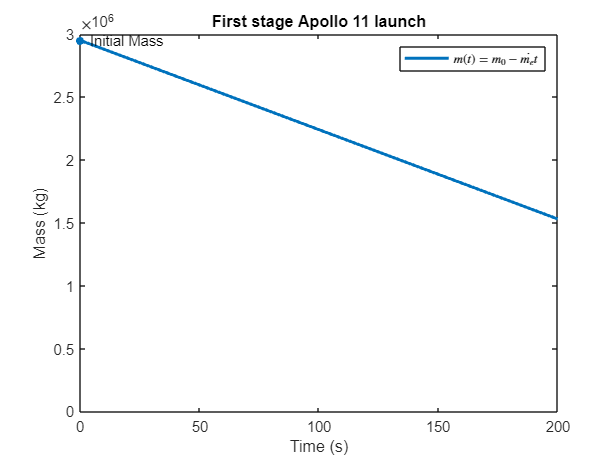

MassFlow = 7100;
SolveMassConservationEquation( me = MassFlow);

 **Reflect**. The amount of rocket fuel used during the first phase of the launch represents emptying 200 average car tanks every second during the 161 seconds of the first phase, for a total of almost 34,000 cars. 

## Solve the Momentum Conservation Equation

Soving the mass conservation equation gave us a solution for the mass of the rocket as a function of time. Now we can consider the conservation of momentum. 

**  Definition. **Integral Form of the Momentum Conservation Equation


$$\underbrace{\frac{\partial}{\partial t}\int_{CV}\rho{\bf u}dV}_\text{Acceleration}
+
\underbrace{\int_{CS}({\bf u}\cdot{\bf n})\rho{\bf u}dS}_\text{Thrust}
=
\Sigma {\bf F}$$


In this part of the script, we will consider the same input parameters as in the previous section, as well as the solution from the mass conservation equation,

$m(t) = m_0 - \dot{m_e}t$.

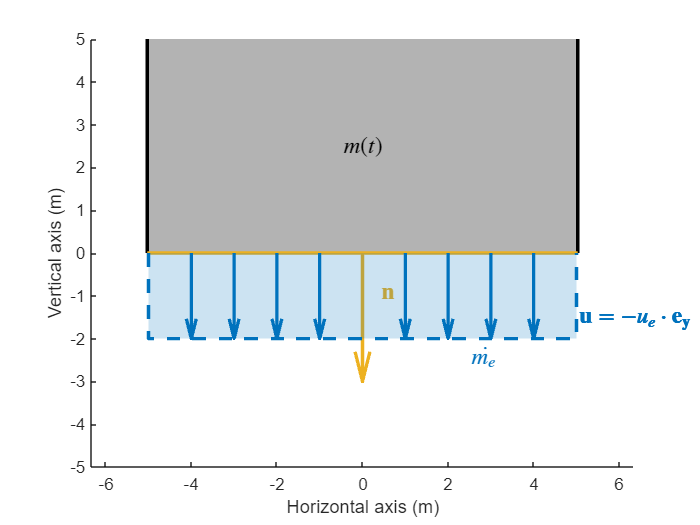

figure()
DrawSaturn(Highlight="CSB", ZoomIn=true, NormalVector=true, DrawExhaustVelocity=true, WriteExhaustVelocity=true, ...
    DrawExhaustMassFlow=true, WriteExhaustMassFlow=true, WriteMass=true);

### **Simplifying Momentum Conservation**

  **Pro-tip**. The first step in solving the momentum conservation equation is identical to the first step used for the mass conservation equation. In this case, the thrust term is broken down across the different control surfaces.


$$\frac{\partial}{\partial t}\int_{CV}\rho{\bf u}dV
+
\int_{CS}({\bf u}\cdot{\bf n})\rho{\bf u}dS
= 
\Sigma {\bf F}\\
\frac{\partial}{\partial t}\int_{CV}\rho{\bf u}dV
+
\int_{CS_\text{right}}({\bf u}\cdot{\bf n})\rho{\bf u}dS
+
\int_{CS_\text{left}}({\bf u}\cdot{\bf n})\rho{\bf u}dS
+
\int_{CS_\text{bottom}}({\bf u}\cdot{\bf n})\rho{\bf u}dS
= 
\Sigma {\bf F}\\
$$
       
$$(\spadesuit)$$


  **Pro-tip. **The second step is identical to the second step from the mass conservation equation. We want to identify the terms that are equal to zero.

 **Exercise**. In the case of Saturn V, identify the terms that are equal to zero, if any.

`CSR `= $\displaystyle \int_{CS_{\text{right}}} (\bf u \cdot \bf n) \rho \bf u \; dS$  

`CSL `= $\displaystyle \int_{CS_{\text{left}}} (\bf u \cdot \bf n) \rho \bf u \; dS$   

`CSB `= $\displaystyle \int_{CS_{\text{bottom}}} (\bf u \cdot \bf n) \rho \bf u \; dS$

qNullTermMomentum(CSR = true, ...
                  CSL = true, ...
                  CSB = false);

Good job! You found all of the term equal to zero.


### Derivation of the Acceleration Term

** Assumption. **The acceleration term due to the propellant motion within the rocket itself is negligible.


$$\frac{\partial}{\partial t}\int_{CV}\rho{\bf u}dV = 0\\$$


Thus, the equation $(\spadesuit)$ reduces to:


$$\int_{CS_\text{bottom}}({\bf u}\cdot{\bf n})\rho{\bf u}dS
= 
\Sigma {\bf F}\\
$$


### Projection over the Reference Frame

  **Pro-tip. **The momentum conservation equation equation differs from other conservation equations as its conserved quantity is a vector. At this point in the calculation, it is important to express the equation along each axis of the domain.

** Assumption. **As a first approximation of the rocket's trajectory, we are considering a flight path that is purely vertical with no horizontal displacement.

Therefore, the remaining equation is solely along the $y$-axis of the domain.


$$\int_{CS_\text{bottom}}({\bf u}\cdot{\bf n})\rho({\bf u}\cdot{\bf e_y})dS = \Sigma{\bf F_y}$$


### Integral Thrust Term

  **Pro-tip**. To avoid a sign error in the calculation of the thrust term, it can help to estimate the direction of the thrust along a control surface.

 **Exercise.** Does the thrust from the mass flow leaving the rocket through the bottom control surface result in force sideways, upward, or downward? 

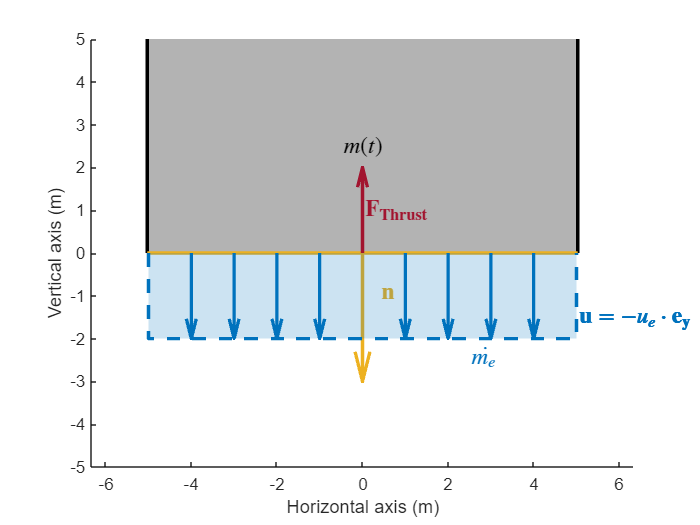

qThrustDirection( "Upward");

 **Exercise.** What is the sign resulting from the two dot product in $\displaystyle \int_{CS_\text{bottom}}({\bf u}\cdot{\bf n})\rho({\bf u}\cdot{\bf e_y})dS 
=
\int_{CS_\text{bottom}} \pm u_e \rho u_e dS
$? Is it zero, positive or negative?

qThrustSign(2);

Good job!


 **Reflect**. The sign of the thrust is opposite to the direction of its resulting force.

 **Exercise.** Assume the exhaust velocity and exhaust mass flow are constant and uniform. How can $\displaystyle \int_{CS_\text{bottom}}({\bf u}\cdot{\bf n})\rho({\bf u}\cdot{\bf e_y})dS$ be expressed in terms of $m_0
$, $u_e$,  $\dot{m_e}$, and $m_p$? 


$$\text{A) } u_e^2\dot{m_e}
\quad\quad
\text{B) } -u_e\dot{m_e}
\quad\quad
\text{C) } -\dot{m_e}
\quad\quad
\text{D) } -u_e^2$$


Good job!


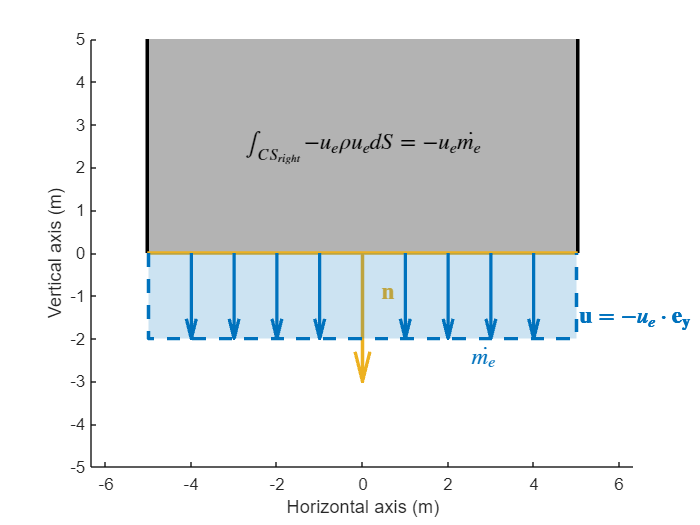

qThrustTerm("B");

### Body Forces 

The last remaining term to develop in the momentum conservation equation is the sum of the body forces. Because we considered the trajectory to be purely vertical, we will only consider the forces with vertical component.

  **Pro-tip**. The first step should always be to identify the body forces acting on our control volume.

 **Exercise.** What forces should be included in the body force term?

qBodyForces( Gravity = true, ...
             Spring = false, ...
             Electric = false, ...
             Friction = true, ...
             Magnetic = false, ...
             Thrust = false, ...
             Acceleration = true);

Good Job! You identified all the right body forces for this problem.


** Assumption. **As a first approximation for the forces acting on the rocket, we assume the following:

- Air resistance force is negligible compared to the thrust.

- Gravity is constant with respect to the altitude during the first phase of the launch and is taken equal to the gravity at sea-level.

 **Exercise**. What is the correct expression for the gravitational forces acting on the rocket?


$$\text{A) } g\times m_0
\quad\quad
\text{B) } -g\times m_0 
\quad\quad
\text{C) } g \times \dot{m_e}
\quad\quad
\text{D) } -g \times m(t)$$


qGravityTerm(4);

Good job!


Because the control volume is constantly accelerating during the launch, the rocket is experiencing an accelerating force. This is just like the accelerating force we feel while driving a car or going on a roller coaster.

 **Exercise**. What is the direction of the acceleration force experience by the rocket?

Good job! Resulting forces are always directed in the opposite direction of their sources.


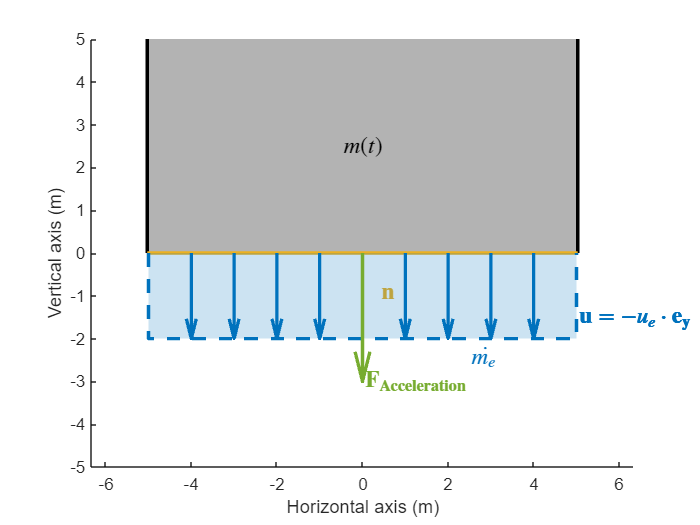

qAccelerationDirection("Downward");

 **Exercise**. What is the expression of the acceleration force experienced by the rocket? Where $y_r$ represents the altitude of the Control Volume (Rocket).


$$\text{A) } m(t)\frac{d^2y_r}{dt^2}
\quad\quad
\text{B) } -m(t)\frac{d^2y_r}{dt^2}
\quad\quad
\text{C) } \dot{m_e}\frac{d^2y_r}{dt^2}
\quad\quad
\text{C) } -\dot{m_e}\frac{d^2y_r}{dt^2}$$


qAccelerationTerm(1);

### Solve Momentum Conservation Equation


$$\frac{\partial}{\partial t}\int_{CV}\rho{\bf u}dV
+
\int_{CS}({\bf u}\cdot{\bf n})\rho{\bf u}dS
= 
\Sigma {\bf F}\\$$



$$-u_e\dot{m_e}
= 
-\frac{d^2y_r}{dt^2}-m(t)g$$



$$\frac{d^2 y_r}{dt^2}= \frac{u_e\dot{me}}{m(t)}-g$$


** Summary. **This differential equation models the trajectory of the Saturn V assuming:

- The exhaust mass flow out of the rocket engine is constant during the flight.

- The flight performance of the rocket are constant during the first phase of the flight.

- The rocket is flying verticaly, there is no horizontal discplacement.

- The air resistance is neglected against the thrust from the rocket engine.

- The gravity is considered independent of the altitude and constant during the first phase of the flight.

  **Try**. Use the following button to compute the altitude of the rocket with respect to time and compare it to the flight data recorded during the Apollo 11 mission.

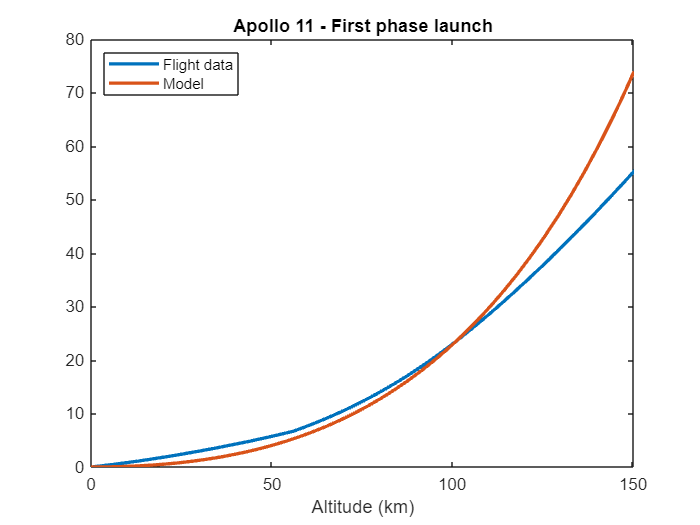

 
SolveMomentum( me = MassFlow, angle=false, gravity=false );

 **Reflect**. Mass Conservation Equation -> m(t) | Momentum -> y(t)

## Analysis of the model

The model seems to be in good agrement with the 

 **Exercise. **Which one of th

qSourceInaccuracy( BadPhysics = false, ...
                   Friction = true, ...
                   FlightPath = true, ...
                   Gravity = true, ...
                   Performance = true);

Good job!


 **Reflect**. In the remaining section of the script, we will address some of the inaccuracy causes.

### **Correction for Gravity**

In the previous section we considered the gravity to be constant with the altitude. We can defined the following equation to have the gravity vary with respect to the altitude where $G
$ is the gravitational constant, $M_t $ is Earth mass, $r_t$ is Earth radius and $y_r
$ is the rocket's altitude.


$$g(y_r) = \frac{GM_t}{(r_t+y_r)^2}$$


  **Try**. Use the following button to compute the altitude of the rocket with respect to time and compare it to the flight data recorded during the Apollo 11 mission.


$$\frac{d^2 y_r}{dt^2}= \frac{u_e\dot{me}}{m(t)}-g(y_r)$$


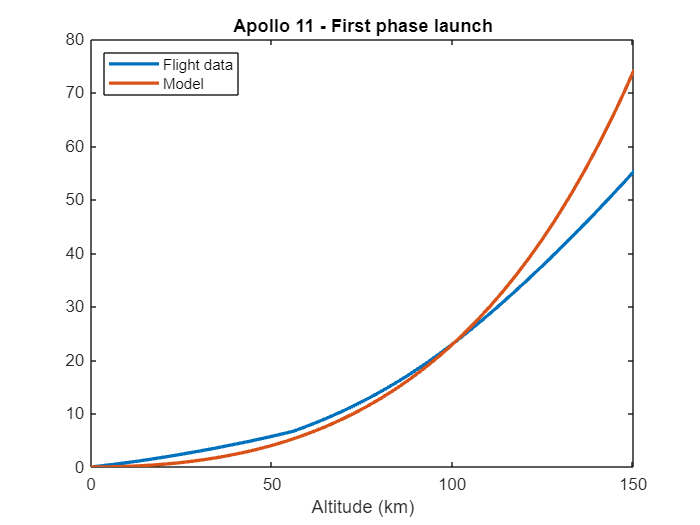

 
SolveMomentum( me = MassFlow, angle=false, gravity=true );

### Correction for rocket flight path angle

In the previous section, we consider that the trust of the rocket was directed verticaly and therefore the flight path of the rocket should be purely vertical. However, the flight path of Apollo 11 was not directed directly verticaly. The mission consisted a getting the spacecraft into earth orbit for a couple of revolution before the start the translunar injection.

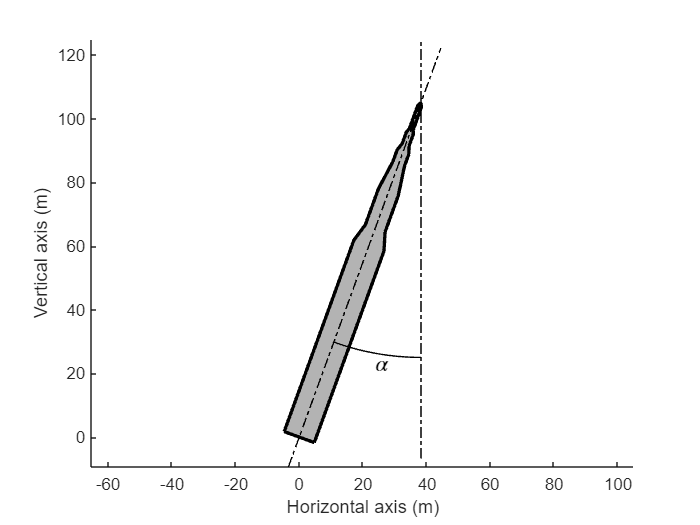

figure()
DrawSaturn(PathAngle=20);


$$\underbrace{\frac{d^2 y_r}{dt^2}}_\text{A}
=
\underbrace{ \frac{u_e\dot{me}}{m(t)}}_\text{B}
-
\underbrace{g}_\text{C}$$


 **Exercise. **What term in the final differential equation should be modified to take into account the path angle of the rocket?

qAngleTerm(2);

Good job!



$$\frac{d^2 y_r}{dt^2}
=
 (?)\frac{u_e\dot{me}}{m(t)}
-
g$$


 **Exercise. **What should (?) be equal to?


$$\text{A) } sin(\alpha)
\quad\quad
\text{B) } \frac{1}{sin(\alpha)}
\quad\quad
\text{C) } cos(\alpha)
\quad\quad
\text{C) }  \frac{1}{cos(\alpha)}$$


Good job!


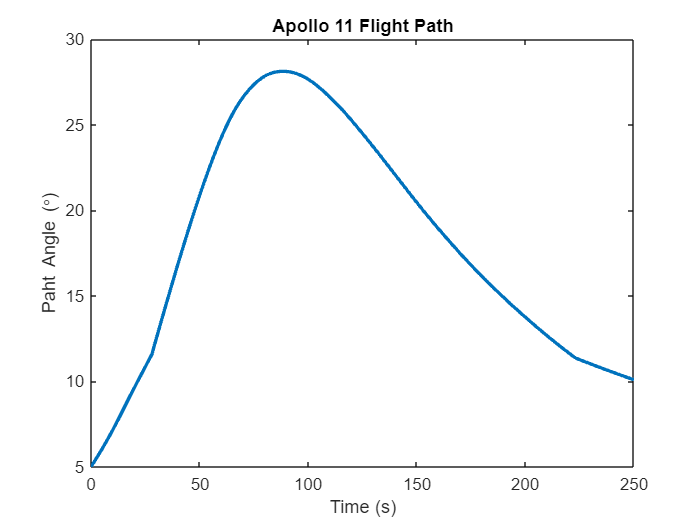

qTrigFunction(3);


$$\frac{\partial^2y(t)}{\partial t^2}=cos(\alpha(t))\frac{\dot{m_e}u_e}{m_o-\dot{m_e}t} - g$$


  **Try**. Use the following button to compute the altitude of the rocket with respect to time and compare it to the flight data recorded during the Apollo 11 mission.

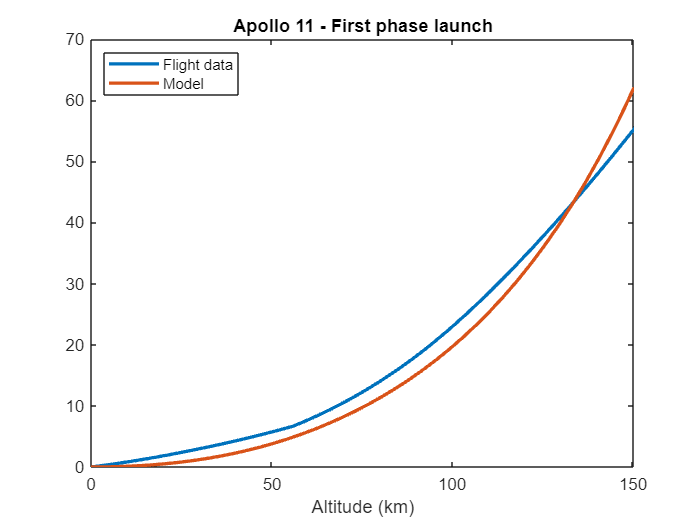

 
SolveMomentum( me = MassFlow, angle=true, gravity=true );

 **Reflect**. Adding the dependence on the path angle taken by the rocket decreases the accuracy of the model. 

## Conclusion

 **Reflect**. The differential equation resulting from the Momentum Conservation equation is solved using MATLAB's Ordinary Differential Equation solver [ode45](https://www.mathworks.com/help/matlab/ref/ode45.html)

 **Reflect**. Use the following button to show the Rocket Path from lift-off to translunar injection.

 
ShowRocketPath()

 **Reflect**. Hyperlink to Buckingham-Pi script for the air resistance script

## Helper Functions

If you wish to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

function ax = DrawSaturn(opts)
    arguments
        opts.ControlVolume (1,1) uint8 {mustBeMember(opts.ControlVolume, [0 1 2 3])} = 0
        opts.PathAngle (1,1) double = 0
        opts.DrawFootball (1,1) logical = false
        opts.Highlight (1,1) string {mustBeMember(opts.Highlight, ["none", "CV", "CSR", "CSL", "CSB"])} = "none"
        opts.NormalVector (1,1) logical = false
        opts.Gravity (1,1) logical = false
        opts.ZoomIn (1,1) logical = false
        opts.DrawExhaustVelocity (1,1) logical = false
        opts.DrawExhaustMassFlow (1,1) logical = false
        opts.WriteExhaustVelocity (1,1) logical = false
        opts.WriteExhaustMassFlow (1,1) logical = false
        opts.WriteMass (1,1) logical = false
        opts.DrawThrust (1,1) logical = false
        opts.DrawAcceleration (1,1) logical = false
        opts.WriteEquation (1,1) string = ""
    end

    % Define the axis:
    ax = axes;
    xlabel(ax, "Horizontal axis (m)")
    ylabel(ax, "Vertical axis (m)")
    axis equal
    hold on
    ColorHighlight = ax.ColorOrder(3,:);

    % Control Volume background
    if opts.ControlVolume == 1 || opts.ControlVolume == 3
        patch([-40 40 40 -40],[0 0 120 120], ax.ColorOrder(1,:), "FaceAlpha", 0.2)
        line([-40 40],[120 120] ,"Color", ax.ColorOrder(1,:), "LineWidth", 2, "LineStyle", "--")
        line([ 40 40],[0 120] ,"Color", ax.ColorOrder(1,:), "LineWidth", 2, "LineStyle", "--")
        line([-40 -40],[0 120] ,"Color", ax.ColorOrder(1,:), "LineWidth", 2, "LineStyle", "--")
    end 
    

    % Plot rocket:
    xR = [ 0 5.0292 5.0292 3.302 3.302 1.9558 1.9558 1.143 1.143 0.635 0.635 0];
    yR = [ 0 0 63.9826 69.7484 81.838 91.313 95.2246 97.7646 101.6 102.87 110.49 111.76];
    if opts.Highlight ~= "CV"
        patch( xR, yR, [0.7 0.7 0.7], "EdgeColor", "none")
        patch(-xR, yR, [0.7 0.7 0.7], "EdgeColor", "none")
    else
        patch( xR, yR, ColorHighlight, "EdgeColor", "none")
        patch(-xR, yR, ColorHighlight, "EdgeColor", "none")
    end

    % Right Control Surface
    if opts.Highlight == "CSR"
        line( xR(2:end),yR(2:end),"Color", ColorHighlight, "LineStyle", "-", "LineWidth", 2)
        if     opts.NormalVector 
            if opts.ZoomIn
                Pos = [xR(2) 2.0 0.0]';
                Dir = [3.0 0.0 0.0]';
            else
                Pos = [xR(2) 40.0 0.0]';
                Dir = [20.0 0.0 0.0]';
            end
            xy = rotz(-opts.PathAngle)*Pos;
            uv = rotz(-opts.PathAngle)*Dir;
            quiver(xy(1),xy(2),uv(1),uv(2), 0.0, AutoScale="off", LineWidth=2, Color=ColorHighlight, MaxHeadSize=0.7);
            text(xy(1)+0.5*uv(1)+0.2*norm(uv), xy(2)+0.5*uv(2)+0.2*norm(uv), "${\bf n}$", Interpreter="latex", ...
                HorizontalAlignment="center", Color=ColorHighlight, Rotation=-opts.PathAngle, FontSize=14)
        end
    elseif opts.ControlVolume == 1 || opts.ControlVolume == 2
        line( xR(2:end),yR(2:end),"Color", ax.ColorOrder(1,:) , "LineStyle", "--", "LineWidth", 2)
    elseif  opts.ControlVolume == 3
    else
        line( xR(2:end),yR(2:end),"Color", [0 0 0], "LineStyle", "-", "LineWidth", 2)
    end

    % Left Control Surface
    if opts.Highlight == "CSL"
        line( -xR(2:end),yR(2:end),"Color", ColorHighlight, "LineStyle", "-", "LineWidth", 2)
        if     opts.NormalVector 
            if opts.ZoomIn
                Pos = [-xR(2) 2.0 0.0]';
                Dir = [-3.0 0.0 0.0]';
            else
                Pos = [-xR(2) 40.0 0.0]';
                Dir = [-20.0 0.0 0.0]';
            end
            xy = rotz(-opts.PathAngle)*Pos;
            uv = rotz(-opts.PathAngle)*Dir;
            quiver(xy(1),xy(2),uv(1),uv(2), 0.0, AutoScale="off", LineWidth=2, Color=ColorHighlight, MaxHeadSize=0.7);
            text(xy(1)+0.5*uv(1)+0.2*norm(uv), xy(2)+0.5*uv(2)+0.2*norm(uv), "${\bf n}$", Interpreter="latex", ...
                HorizontalAlignment="center", Color=ColorHighlight, Rotation=-opts.PathAngle, FontSize=14)
        end
    elseif opts.ControlVolume == 1 || opts.ControlVolume == 2
        line( -xR(2:end),yR(2:end),"Color", ax.ColorOrder(1,:) , "LineStyle", "--", "LineWidth", 2)
    elseif  opts.ControlVolume == 3
    else
        line( -xR(2:end),yR(2:end),"Color", [0 0 0], "LineStyle", "-", "LineWidth", 2)
    end

    % Bottom Control Surface
    if opts.Highlight == "CSB"
        line([-xR(2) xR(2)], [yR(2) yR(2)],"Color", ColorHighlight, "LineStyle", "-", "LineWidth", 2)
        if     opts.NormalVector 
            if opts.ZoomIn
                Pos = [0 0 0.0]';
                Dir = [0.0 -3 0.0]';
            else
                Pos = [0 0 0.0]';
                Dir = [0.0 -20 0.0]';
            end
            xy = rotz(-opts.PathAngle)*Pos;
            uv = rotz(-opts.PathAngle)*Dir;
            quiver(xy(1),xy(2),uv(1),uv(2), 0.0, AutoScale="off", LineWidth=2, Color=ColorHighlight, MaxHeadSize=0.7);
            text(xy(1)+0.5*uv(1)+0.2*norm(uv), xy(2)+0.5*uv(2)+0.2*norm(uv), "${\bf n}$", Interpreter="latex", ...
                HorizontalAlignment="center", Color=ColorHighlight, Rotation=-opts.PathAngle, FontSize=14)
        end
    elseif opts.ControlVolume == 2
        line([-xR(2) xR(2)], [yR(2) yR(2)],"Color", ax.ColorOrder(1,:), "LineStyle", "--", "LineWidth", 2)
    elseif opts.ControlVolume == 1 || opts.ControlVolume == 3
    else
        line([-xR(2) xR(2)], [yR(2) yR(2)],"Color", [0 0 0], "LineStyle", "-", "LineWidth", 2)
    end
    
    % Draw football field
    if opts.DrawFootball
        xF = [40 89 89 40];
        yF = [0 0 9.1 9.1];
        patch(xF,yF, ax.ColorOrder(7,:))
        for i = 1:10
            yF = yF + 9.1;
            patch(xF,yF,ax.ColorOrder(5,:))
            if i ~= 1
                text(42.5, (i*10)*0.91, sprintf("%i 0", i-1), "Rotation",90,"Color","w","HorizontalAlignment","center","FontWeight","bold")
                text(86.5, (i*10)*0.91, sprintf("%i 0", 11-i), "Rotation",-90,"Color","w","HorizontalAlignment","center","FontWeight","bold")
            end
        end
        yF = yF + 10*0.9144;
        patch(xF,yF,ax.ColorOrder(7,:))
    end

    if opts.DrawExhaustVelocity && opts.ZoomIn
        for i = 1:4
            quiver( i, 0.0, 0, -2, 0.0, "AutoScale", "off", "LineWidth", 2, "Color", ax.ColorOrder(1,:), "MaxHeadSize", 0.7);
            quiver( -i, 0.0, 0, -2, 0.0, "AutoScale", "off", "LineWidth", 2, "Color", ax.ColorOrder(1,:), "MaxHeadSize", 0.7);
            if opts.WriteExhaustVelocity
                text(5.0, -1.5, "${\bf u} = -u_e\cdot{\bf e_y}$", "Interpreter", "latex", "FontSize",14, "Color", ax.ColorOrder(1,:))
            end
        end
    end

    if opts.DrawExhaustMassFlow && opts.ZoomIn
        patch([-5 5 5 -5], [-2 -2 0 0], ax.ColorOrder(1,:), "FaceAlpha", 0.2, "LineStyle", "none")
        line([-5 -5 5 5], [0 -2 -2 0], "Color",ax.ColorOrder(1,:), "LineStyle", "--", "LineWidth", 2)
        if opts.WriteExhaustMassFlow
            text(2.5, -2.4, "$\dot{m_e}$", "Interpreter", "latex", "FontSize",14, "Color", ax.ColorOrder(1,:))
        end
    end    
    
    if opts.PathAngle ~= 0
        line([0 0], [-10 130], "LineStyle","-.", "Color", "k")
        hl = line([0 0], [0 yR(end)+20], "LineStyle", "-.","Color", "k");
        rotate(hl, [0 0 1], opts.PathAngle, [0 yR(end) 0])
        i = linspace(0,opts.PathAngle, 100);
        x = 80*cosd(i-90);
        y = 80*sind(i-90)+yR(end);
        hold on
        plot(x,y, "k-")
        text(mean(x), mean(y)-4, "$\alpha$", "Interpreter", "latex", "FontSize",14)    
        child = allchild(ax);
        rotate(child, [0 0 1], -opts.PathAngle, [0 0 0])
    end

    if opts.WriteMass
        text(0.0, 2.5, "$m(t)$", "Interpreter","latex","HorizontalAlignment","center", "FontSize",14)
    end
   
    if opts.DrawThrust
        xPos = [0.0 0.0];
        if opts.ZoomIn
            xDir = [0.0 2.0];
        else
            xDir = [0.0 20.0];
        end
        quiver(xPos(1),xPos(2), xDir(1), xDir(2),0.0,"AutoScale","off","LineWidth",2, "Color",ax.ColorOrder(7,:), "MaxHeadSize",0.7)
        text(xPos(1)+0.5*xDir(1), xPos(2)+1.0, "${\bf F_{Thrust}}$", "Interpreter","latex","Color",ax.ColorOrder(7,:), "FontSize",14)
    end

    if opts.DrawAcceleration
        xPos = [0.0 0.0];
        if opts.ZoomIn
            xDir = [0.0 -3.0];
        else
            xDir = [0.0 -20.0];
        end
        quiver(xPos(1),xPos(2), xDir(1), xDir(2),0.0,"AutoScale","off","LineWidth",2, "Color",ax.ColorOrder(5,:), "MaxHeadSize",0.7)
        text(xPos(1), xPos(2)+xDir(2), "${\bf F_{Acceleration}}$", "Interpreter","latex","Color",ax.ColorOrder(5,:), "FontSize",14)
    end

    if opts.Gravity
        xPos = [2.0 4.0];
        if opts.ZoomIn
            xDir = [0.0 -3.0];
        else
            xDir = [0.0 -20.0];
        end
        quiver(xPos(1),xPos(2), xDir(1), xDir(2),0.0,"AutoScale","off","LineWidth",2, "Color", "k", "MaxHeadSize",0.7)
        text(xPos(1), xPos(2)+xDir(2), "${\bf g}$", "Interpreter","latex","Color", "k", "FontSize",14)
    end

    if opts.ControlVolume == 1
        line([5.0292 40],[0 0] ,"Color", ax.ColorOrder(1,:), "LineWidth", 2, "LineStyle", "--")
        line([-5.0292 -40],[0 0] ,"Color", ax.ColorOrder(1,:), "LineWidth", 2, "LineStyle", "--")
    end
    if opts.ControlVolume == 3
        line([-40 40],[0 0] ,"Color", ax.ColorOrder(1,:), "LineWidth", 2, "LineStyle", "--")
    end

    hold off

    if opts.ZoomIn
        ylim([-5 5])
    end
end

function qControlVolumeDefinition( str )
    arguments
        str (1,1) string { mustBeMember(str, ["None", "First", "Second", "Third"]) } = "None"
    end
    
    switch (str)
        case "None"
            warning("Please, select one of the three proposed Control Volume definitions.")
        case "First"
        case "Second"
            disp("Good job!")
        case "Third"
    end

end


function IntroControlVolume(str)
    arguments
        str (1,1) string {mustBeMember(str, ["none", "CV", "CSR", "CSL", "CSB"])} = none
    end

    figure()
    DrawSaturn(Highlight=str);
    title("Control Volume and Surfaces")
end

function qNormalBottomSurface(str)
    arguments
        str (1,1) string {mustBeMember(str, ["none","Sideways", "Upward", "Downward"])} = none
    end
    figure()
    ax = DrawSaturn(ZoomIn=true, Highlight="CSB");
    hold on
    switch (str)
        case "none"
            Feedback = "Please select either Sideways, Upward or Downward";
            Color    = "r";
        case "Sideways"
            Feedback = "Because the surface is horizontal, the normal vector to the surface is necessarly vertical";
            Color    = "r";
        case "Upward"
            quiver(0,0,0,3,0,"AutoScale","off","MaxHeadSize",0.7,"Color", ax.ColorOrder(3,:), "LineWidth",2)
            Feedback = "Remember that, by convention, the normal vector is defined as going outward from the control volume, so it can not be upward";
            Color    = "r";
        case "Downward"
            quiver(0,0,0,-3,0,"AutoScale","off","MaxHeadSize",0.7,"Color", ax.ColorOrder(3,:), "LineWidth",2)
            Feedback = "Good job! Remember that, by convention, the normal vector is defined as going outward from the control volume.";
            Color    = "g";
    end
    hold off
    boxPos = ax.Position;
    boxPos([1 3]) = boxPos([1 3]) + [0.2 -0.4];
    if str == "Upward"
        boxPos([2 4]) = [0.2 0.2];
    else
        boxPos([2 4]) = [0.6 0.2]; 
    end

    annotation("textbox", boxPos, "String", Feedback, "HorizontalAlignment","center", ...
               "VerticalAlignment","middle", "EdgeColor","none","Color",Color)
    title("Control volume around the bottom of rocket")
end

function qNullTermMass(opts)
    arguments
        opts.A (1,1) logical
        opts.B (1,1) logical
        opts.C (1,1) logical
        opts.D (1,1) logical
    end

    if ( opts.A )
        warning("The mass of the rocket is decreasing during the launch as the rocket, as rocket fuel is being used as propellant.")
    end
    if ( opts.D )
        warning("The propellant is exiting the rocket from the bottom surface control, therefore this mass flux can not be equal to zero.")
    end
    
    % XXX Add feedback in case of wrong answer
    if (~opts.A && opts.B && opts.C && ~opts.D)
        disp("Good job! You indentified all of the null term in the mass conservation equation.")
    end
end

function qInertiaMass(int)
    arguments
        int (1,1) uint8 {mustBeMember(int, [0 1 2 3 4])} = 0
    end
    switch (int)
        case 0
            warning("Please select one of the possible answers.")
        case 1
            disp("Good job! This answer is correct.")
        case 2
            warning("The velocity is not part of this integral")
        case 3
            warning("The velocity is not part of this integral.")
        case 4
            warning("Check your units. This is not correct.")
    end
end

function qDotProductMass(int)
    arguments
        int (1,1) uint8 {mustBeMember(int, [0 1 2])} = 0
    end
    
    switch (int)
        case 0
            warning("Please select one of the possible answer.")
        case 1
            warning("Wrong! Because the direction of the velocity vector is the same as the normal surface vector, their scalar product is positive.")
        case 2
            disp("Good job! The vectors are in the same direction so the scalar product is postive.")
    end

end

function qThrustDirection(str)
    arguments
        str (1,1) string {mustBeMember(str, ["None", "Sideways", "Upward", "Downward"])} = "None"
    end

    switch (str)
        case "None"
            warning("Please select either Sideways, Upward and Downward.")
        case "Sideways"
            warning("Wrong! The resulting thrust is parallel to the exhaust velocity! Try Again!")
        case "Upward"
            figure()
            DrawSaturn(ZoomIn=true, Highlight="CSB", NormalVector=true, DrawExhaustVelocity=true, ...
                DrawExhaustMassFlow=true, WriteExhaustVelocity=true, WriteExhaustMassFlow=true, ...
                WriteMass=true, DrawThrust=true, DrawAcceleration=false);
        case "Downward"
    end
end

function qAccelerationDirection(str)
    arguments
        str (1,1) string {mustBeMember(str, ["None", "Sideways", "Upward", "Downward"])} = "None"
    end

    switch (str)
        case "None"
            warning("Please select either Sideways, Upward and Downward.")
        case "Sideways"
            warning("Wrong, the resulting thrust is parallel to the exhaust velocity! Try Again!")
        case "Upward"
            warning("Wrong, the force due to the acceleration of the control volume is in opposite direction of the acceleration. Just like we experience an force pushing us forward while using the break in a car.")
        case "Downward"
            disp("Good job! Resulting forces are always directed in the opposite direction of their sources.")
            figure()
            DrawSaturn(ZoomIn=true, Highlight="CSB", NormalVector=true, DrawExhaustVelocity=true, ...
                DrawExhaustMassFlow=true, WriteExhaustVelocity=true, WriteExhaustMassFlow=true, ...
                WriteMass=true, DrawAcceleration=true);
    end
    % XXX Add more feedback
end

function qBodyForces(opts)
    arguments 
        opts.Gravity (1,1) logical
        opts.Spring (1,1) logical
        opts.Electric (1,1) logical
        opts.Friction (1,1) logical
        opts.Magnetic (1,1) logical
        opts.Thrust (1,1) logical 
        opts.Acceleration (1,1) logical
    end
    
    if (opts.Gravity && ~opts.Spring && ~opts.Electric && ...
        opts.Friction && ~opts.Magnetic && ~opts.Thrust && ...
        opts.Acceleration )
        disp("Good Job! You identified all the right body forces for this problem.")
    elseif (opts.Thrust)
        warning("Remember that the thrust term are already accounted for in the integral term over the Control Surfaces, no need to ")
    end

end

function qNullTermMomentum(opts)
    arguments
        opts.CSR (1,1) logical
        opts.CSL (1,1) logical
        opts.CSB (1,1) logical
    end
    
    if opts.CSR && opts.CSL && ~opts.CSB
        disp("Good job! You found all of the term equal to zero.")
    else
        warning("Wrong! There is at least one error, remember the results from the same question applied to the mass conservation equation.")
    end
end

function qThrustSign(int)
    arguments
        int (1,1) uint8 {mustBeMember(int, [0 1 2])} = 0
    end
    
    switch int
        case 0
            warning("Please select either negative or positive.")
        case 1
            warning("Wrong! Be careful, the sign of the two scalar product are different.")
        case 2
            disp("Good job!")
    end
end

function qThrustTerm(str)
    arguments
        str (1,1) string {mustBeMember(str, ["None", "A", "B", "C", "D"])}
    end

    figure()
    DrawSaturn(ZoomIn=true, Highlight="CSB", NormalVector=true, DrawExhaustVelocity=true, DrawExhaustMassFlow=true, ...
               WriteExhaustMassFlow=true, WriteExhaustVelocity=true);
    
    switch (str)
        case "None"
            warning("Please select A, B, C or D.")
        case "A"
            
        case "B"
            disp("Good job!")
            text(0.0, 2.5, "$\int_{CS_{right}} -u_e \rho u_e dS = -u_e\dot{m_e}$", ...
                "Interpreter", "latex", "HorizontalAlignment","center", "VerticalAlignment", "middle", "FontSize", 14)
        case "C"

        case "D"

    end

end

function LookAtNormalVector(str)
    arguments
        str (1,1) string {mustBeMember(str, ["none", "CSR", "CSL", "CSB"])} = none
    end
    figure()
    DrawSaturn(Highlight=str, NormalVector=true);
    title("Control Surface Normal Vector")
    xlim([-80 80])
    ylim([-22 115])
end

function qMassFlowTerm(int)
    arguments
        int (1,1) uint8 {mustBeMember(int, [0,1,2,3])} = 0
    end
    switch int
        case 0
            warning("Please select one of the possible answer.")
        case 1
            warning("The result should be positive.")
        case 2
            warning("Please select one of the possible answer.")
        case 3
            disp("Good job! The remaining term in the mass conservation equation represent the mass flow leaving the control volume through the bottom Control Surface.")
    end


end

function SolveMassConservationEquation( opts )
    arguments
        opts.me (1,1) double {mustBeGreaterThan(opts.me, 0.0)}
    end

    t = linspace(0,200,2);
    m0 = 2950000;
    mp = 2150000;
    me = opts.me;
    mf = m0 - mp; % Final mass 
    m = @(t) m0 - me*t;
    tf = (m0-mf)/me;
   

    plot(t,m(t),"SeriesIndex",1, "LineWidth",2)
    hold on
    scatter(0.0, m0, 30, "filled", "SeriesIndex", 1 )
    text(4,m0, "Initial Mass")
    
    if tf < 200
        plot([tf 200], [mf mf], "SeriesIndex",2, "LineWidth",2, "LineStyle","--")
        scatter(tf, mf, 30, "filled", "SeriesIndex",2)
        text(tf-4, mf, "Final Mass", "HorizontalAlignment","right")
        legend("$m(t) = m_0 - \dot{m_e}t$", "", "Run out of fuel, $t > t_f$ = "+tf+"s", "","Interpreter","latex")
    else
        legend("$m(t) = m_0 - \dot{m_e}t$", "","Interpreter","latex")
    end
    
    
    hold off
    xlabel("Time (s)")
    ylabel("Mass (kg)")
    xlim([0 200])
    ylim([0 3000000])
    title("First stage Apollo 11 launch")
end

function SolveMomentum( opts )
    arguments 
        opts.me (1,1) double
        opts.gravity (1,1) logical = 0
        opts.angle (1,1) logical = 0
    end

    ue = 2660;
    m0 = 2950000;
    me = opts.me;
    mf = m0 - 2000000;
    tf = (m0-mf)/me;
    
    m  = @(t) m0 - me*t;
    
    if opts.gravity
        g = @(y) 6.67430e-11 * 5.9722e24 ./ ( 6.3781e6 + y ).^2;
    else
        g = @(y) 6.67430e-11 * 5.9722e24 ./ ( 6.3781e6 + 0 ).^2;
    end

    if opts.angle
        load Apollo11.mat FirstPhase
        alpha = @(t) interp1(FirstPhase.t, FirstPhase.Alpha, t, "pchip");
    else
        alpha = @(t) 0.0;
    end

    ddydt = @(t,y) cosd(alpha(t)).*ue*me./m(t)-g(y);
    dfun = @(t,y) [y(2); ddydt(t,y(1))];
    [t,y] = ode45(dfun, [0 tf], [0; 0]);

    t   = t';
    Alt = y(:,1)';
    
    figure()
    load Apollo11.mat FirstPhase
    plot(FirstPhase.t, FirstPhase.Altitude/1000, LineWidth=2)
    hold on
    plot(t, Alt/1000, LineWidth=2)
    hold off
    xlim([0 tf])
    title("Apollo 11 - First phase launch")
    legend("Flight data", "Model", Location="northwest")
    xlabel("Altitude (km)")
end

function qSourceInaccuracy( opts )
    arguments
        opts.BadPhysics (1,1) logical
        opts.Friction (1,1) logical
        opts.FlightPath (1,1) logical
        opts.Gravity (1,1) logical
        opts.Performance (1,1) logical
    end

    if (~opts.BadPhysics && opts.Friction && opts.FlightPath && ...
         opts.Gravity && opts.Performance)
        disp("Good job!")
    end

    % XXX Add more feedback
end

function ShowRocketPath()
    load Apollo11.mat Launch
    uif = uifigure();
    gg = geoglobe(uif);
    geoplot3(gg,Launch.Lat,Launch.Lon,Launch.El,'y','HeightReference','terrain', 'LineWidth',3)
end

function qGravityTerm(int)
    arguments
        int (1,1) uint8 {mustBeMember(int, [0 1 2 3 4])}
    end

    switch (int)
        case 0
            warning("Please select one of the possible answers.")
        case 1
            warning("The gravitational force depends on the current mass of the control volume.")
        case 2
            warning("The gravitational force depends on the current mass of the control volume.")
        case 3
            warning("The mass flow plays no role in the gravitational force.")
        case 4
            disp("Good job!")
    end

    % XXX Add more feedback
end

function qAccelerationTerm(int)
    arguments
        int (1,1) uint8 {mustBeMember(int, [0 1 2 3 4])}
    end

    switch (int)
        case 0
            warning("Please select one of the possible answer.")
        case 1
        case 2
            disp("Good job!")
        case 3
        case 4
    end

    % XXX Add more Feedback
end

function qAngleTerm(int)
    arguments
        int (1,1) uint8 {mustBeMember(int, [0 1 2 3])}
    end

    switch (int)
        case 0
            warning("Please select one of the possible answer.")
        case 1
        case 2
            disp("Good job!")
        case 3
    end

    % XXX Add more Feedback
end

function qTrigFunction(int)
    arguments
        int (1,1) uint8 {mustBeMember(int, [0 1 2 3 4 ])}
    end

    switch (int)
        case 0
            warning("Please select one of the possible answer.")
        case 1
        case 2
        case 3
            disp("Good job!")
        case 4
    end

    load Apollo11.mat FirstPhase
    figure()
    plot(FirstPhase.t, FirstPhase.Alpha, LineWidth=2)
    xlabel("Time (s)")
    ylabel("Paht Angle (\circ)")
    title("Apollo 11 Flight Path")


    % XXX Add more Feedback
end

[⇦ Return to the navigation page](matlab: OpenOverview)